addpath('functions/');

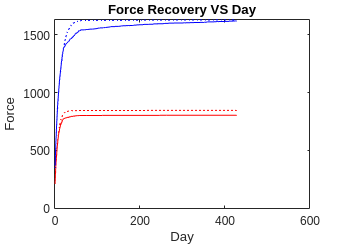

normal_therapy = normal_therapy();
add_acute_dose = add_acute_dose();
add_chronic_dose = add_chronic_dose();

% Creating Patients' Corticalspinal cells.
% Patient 1 - Severely Impaired
n_1 = 1000;

normal_therapy_forces_1 = get_final_forces(normal_therapy, n_1);
add_acute_dose_forces_1 = get_final_forces(add_acute_dose, n_1);
add_chronic_dose_forces_1 = get_final_forces(add_chronic_dose, n_1);

plot(normal_therapy_forces_1, '-', 'Color', 'red')
hold on 
plot(add_acute_dose_forces_1, ':', 'Color', 'red')
hold on 
plot(normal_therapy_forces_1, '--', 'Color', 'red')
hold on

% Patient 2 - moderately Impaired
n_2 = 2000;

normal_therapy_forces_2 = get_final_forces(normal_therapy, n_2);
add_acute_dose_forces_2 = get_final_forces(add_acute_dose, n_2);
add_chronic_dose_forces_2 = get_final_forces(add_chronic_dose, n_2);

plot(normal_therapy_forces_2, '-', 'Color', 'blue')
hold on 
plot(add_acute_dose_forces_2, ':', 'Color', 'blue')
hold on 
plot(normal_therapy_forces_2, '--', 'Color', 'blue')
hold off

% Create graph parameters
title("Force Recovery VS Day")
% ylim([0, 1000])
xlim([0, 600])
ylabel('Force')
xlabel('Day')

saveas(gcf,'images/ForceRecoveryVSDay.png')

Create forces with different rehabilitation methods (r_method) and n CS cells

function final_forces = get_final_forces(r_method, n)
    % Parameters for zero-mean normal distribution
    std_dev = 0.04;
    mean = 0;

    % CS extensor and flexor connection weights
    c_fi = create_cs(0.7, n); 
    c_ei = create_cs(0.3, n); 

    % Translating MN pool to force
    delta = 1;
    
    final_forces = [];
    f_final_net = 0;

    % Initalize the base CS cells
    x_0 = rand(1, n);
    for day_i = 1:length(r_method)
        day = r_method(day_i);
        for trial = 1:day
            v_i = std_dev.*randn(1, n) + mean;
            x_i = x_0 + v_i;
        
            % Flexor MN Pools translated to force
            s_fi = 0;
            for i = 1:n
                s_fi = s_fi + g_i(x_i(i), c_fi(i));
                % s_fi = s_fi + x_i(i) * c_fi(i);
            end
            f_f = delta * s_fi;
            
            % Extensor MN Pools translated to force
            s_ei = 0;
            for i = 1:n
                s_ei = s_ei +  g_i(x_i(i), c_ei(i));
                % s_ei = s_ei + x_i(i) * c_ei(i);
            end
            f_e = delta * s_ei;
        
            % Net force
            f_net = f_f - f_e;
        
            if f_net > f_final_net
                f_final_net = f_net;
                x_0 = x_i;
            end
        end
        % days = [days, day_i];
        % forces = [forces, f_net];
        final_forces = [final_forces, f_final_net];
    end
end